# Plots

Laby Nicolas & Van Mechelen Alex

clc, clearvars
set(groot,'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
set(groot,'defaultLegendLocation','best')

# Basic Q-value algorithm

## 1 Example

exploration function = IdentityExplorationMethod

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

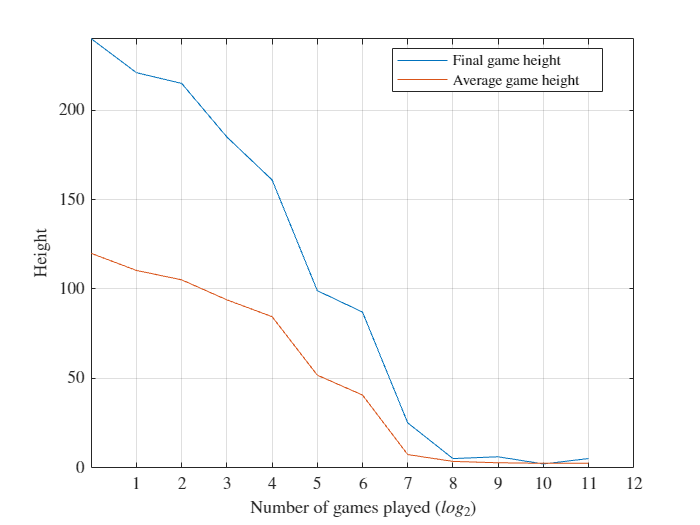

data1 = [1 240 0 768 119.862
2 221 0 1462 110.312
4 215 0 2792 105.042
8 185 0 5242 93.849
16 161 0 9705 84.434
32 99 0 17072 51.697
64 87 0 28460 40.558
128 25 0 44302 7.236
256 5 0 64599 3.413
512 6 0 75030 2.65
1024 2 0 76585 2.353
2048 5 0 76724 2.377];

subplot
plot(log2(data1(:,1)), data1(:,2))
hold on
plot(log2(data1(:,1)), data1(:,5))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("Final game height", "Average game height")

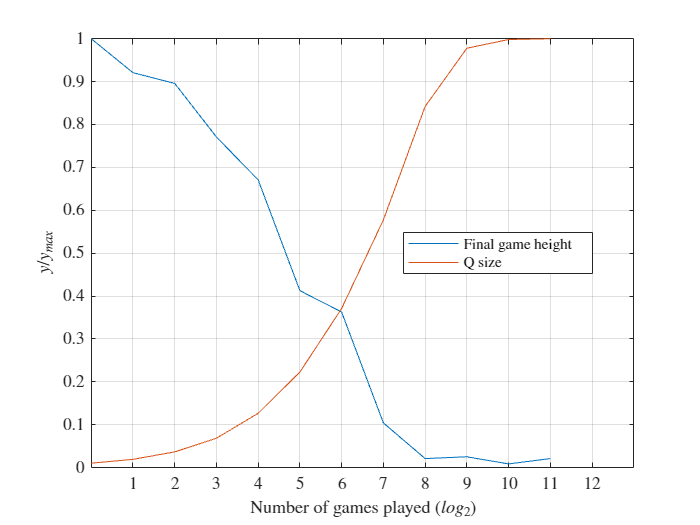


plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Play with discount factor and learning rate

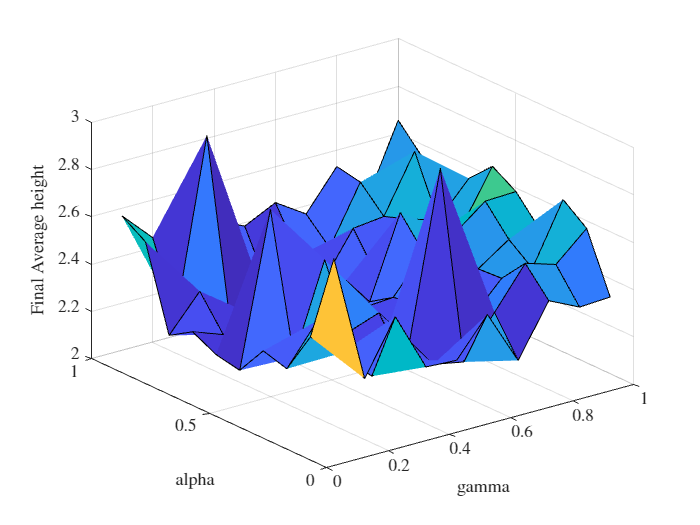

log_data = zeros(12,5,100);
log_data(:,:,1) = importdata('log_gamma_=0.100000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,2) = importdata('log_gamma_=0.200000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,3) = importdata('log_gamma_=0.300000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,4) = importdata('log_gamma_=0.400000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,5) = importdata('log_gamma_=0.500000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,6) = importdata('log_gamma_=0.600000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,7) = importdata('log_gamma_=0.700000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,8) = importdata('log_gamma_=0.800000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,9) = importdata('log_gamma_=0.900000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,10) = importdata('log_gamma_=1.000000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,11) = importdata('log_gamma_=0.100000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,12) = importdata('log_gamma_=0.200000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,13) = importdata('log_gamma_=0.300000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,14) = importdata('log_gamma_=0.400000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,15) = importdata('log_gamma_=0.500000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,16) = importdata('log_gamma_=0.600000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,17) = importdata('log_gamma_=0.700000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,18) = importdata('log_gamma_=0.800000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,19) = importdata('log_gamma_=0.900000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,20) = importdata('log_gamma_=1.000000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,21) = importdata('log_gamma_=0.100000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,22) = importdata('log_gamma_=0.200000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,23) = importdata('log_gamma_=0.300000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,24) = importdata('log_gamma_=0.400000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,25) = importdata('log_gamma_=0.500000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,26) = importdata('log_gamma_=0.600000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,27) = importdata('log_gamma_=0.700000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,28) = importdata('log_gamma_=0.800000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,29) = importdata('log_gamma_=0.900000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,30) = importdata('log_gamma_=1.000000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,31) = importdata('log_gamma_=0.100000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,32) = importdata('log_gamma_=0.200000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,33) = importdata('log_gamma_=0.300000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,34) = importdata('log_gamma_=0.400000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,35) = importdata('log_gamma_=0.500000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,36) = importdata('log_gamma_=0.600000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,37) = importdata('log_gamma_=0.700000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,38) = importdata('log_gamma_=0.800000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,39) = importdata('log_gamma_=0.900000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,40) = importdata('log_gamma_=1.000000_alpha_=0.400000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,41) = importdata('log_gamma_=0.100000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,42) = importdata('log_gamma_=0.200000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,43) = importdata('log_gamma_=0.300000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,44) = importdata('log_gamma_=0.400000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,45) = importdata('log_gamma_=0.500000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,46) = importdata('log_gamma_=0.600000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,47) = importdata('log_gamma_=0.700000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,48) = importdata('log_gamma_=0.800000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,49) = importdata('log_gamma_=0.900000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,50) = importdata('log_gamma_=1.000000_alpha_=0.500000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,51) = importdata('log_gamma_=0.100000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,52) = importdata('log_gamma_=0.200000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,53) = importdata('log_gamma_=0.300000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,54) = importdata('log_gamma_=0.400000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,55) = importdata('log_gamma_=0.500000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,56) = importdata('log_gamma_=0.600000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,57) = importdata('log_gamma_=0.700000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,58) = importdata('log_gamma_=0.800000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,59) = importdata('log_gamma_=0.900000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,60) = importdata('log_gamma_=1.000000_alpha_=0.600000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,61) = importdata('log_gamma_=0.100000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,62) = importdata('log_gamma_=0.200000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,63) = importdata('log_gamma_=0.300000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,64) = importdata('log_gamma_=0.400000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,65) = importdata('log_gamma_=0.500000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,66) = importdata('log_gamma_=0.600000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,67) = importdata('log_gamma_=0.700000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,68) = importdata('log_gamma_=0.800000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,69) = importdata('log_gamma_=0.900000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,70) = importdata('log_gamma_=1.000000_alpha_=0.700000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,71) = importdata('log_gamma_=0.100000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,72) = importdata('log_gamma_=0.200000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,73) = importdata('log_gamma_=0.300000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,74) = importdata('log_gamma_=0.400000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,75) = importdata('log_gamma_=0.500000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,76) = importdata('log_gamma_=0.600000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,77) = importdata('log_gamma_=0.700000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,78) = importdata('log_gamma_=0.800000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,79) = importdata('log_gamma_=0.900000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,80) = importdata('log_gamma_=1.000000_alpha_=0.800000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,81) = importdata('log_gamma_=0.100000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,82) = importdata('log_gamma_=0.200000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,83) = importdata('log_gamma_=0.300000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,84) = importdata('log_gamma_=0.400000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,85) = importdata('log_gamma_=0.500000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,86) = importdata('log_gamma_=0.600000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,87) = importdata('log_gamma_=0.700000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,88) = importdata('log_gamma_=0.800000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,89) = importdata('log_gamma_=0.900000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,90) = importdata('log_gamma_=1.000000_alpha_=0.900000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,91) = importdata('log_gamma_=0.100000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,92) = importdata('log_gamma_=0.200000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,93) = importdata('log_gamma_=0.300000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,94) = importdata('log_gamma_=0.400000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,95) = importdata('log_gamma_=0.500000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,96) = importdata('log_gamma_=0.600000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,97) = importdata('log_gamma_=0.700000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,98) = importdata('log_gamma_=0.800000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,99) = importdata('log_gamma_=0.900000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,100) = importdata('log_gamma_=1.000000_alpha_=1.000000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');

finalAvgHeight = log_data(end,end,:);
AvgAvgHeight = mean(log_data(:,end,:),1);
Avg3AvgHeight = mean(log_data(end-2:end,end,:),1); %avg over 3 last power of 2

x = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
y = [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];

z_final = zeros(10,10);

for i = 1:10
    z_final(i,:) = finalAvgHeight((i-1)*10+1:i*10);
end

surf(x,y,z_final)
ylabel("alpha")
xlabel("gamma")
zlabel("Final Average height")

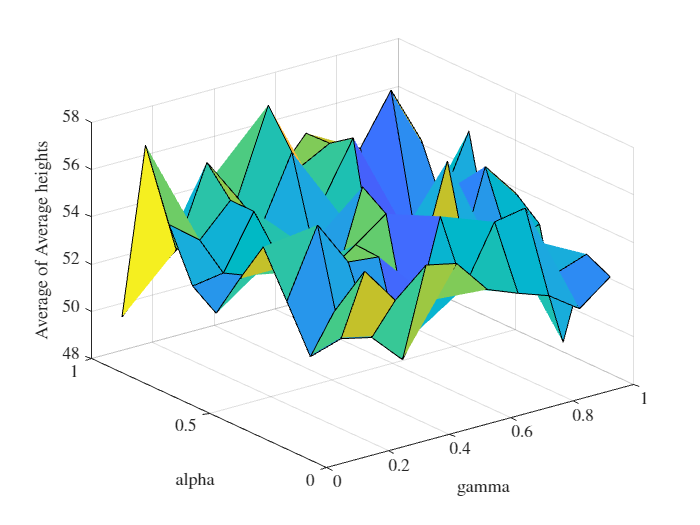


z_avg = zeros(10,10);

for i = 1:10
    z_avg(i,:) = AvgAvgHeight((i-1)*10+1:i*10);
end
surf(x,y,z_avg)
ylabel("alpha")
xlabel("gamma")
zlabel("Average of Average heights")

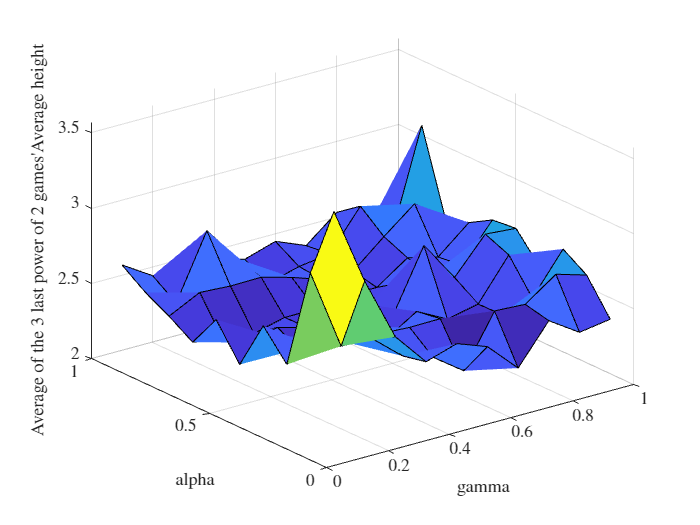



z_avg3 = zeros(10,10);

for i = 1:10
    z_avg3(i,:) = Avg3AvgHeight((i-1)*10+1:i*10);
end
surf(x,y,z_avg3)
ylabel("alpha")
xlabel("gamma")
zlabel("Average of the 3 last power of 2 games'Average height")

Refining

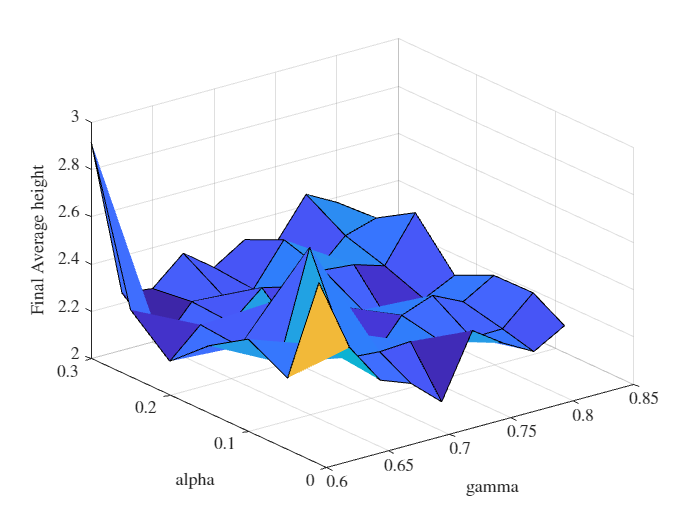

log_data = zeros(12,5,63);
log_data(:,:,1) = importdata('log_gamma_=0.600000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,2) = importdata('log_gamma_=0.625000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,3) = importdata('log_gamma_=0.650000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,4) = importdata('log_gamma_=0.675000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,5) = importdata('log_gamma_=0.700000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,6) = importdata('log_gamma_=0.725000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,7) = importdata('log_gamma_=0.750000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,8) = importdata('log_gamma_=0.775000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,9) = importdata('log_gamma_=0.800000_alpha_=0.010000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,10) = importdata('log_gamma_=0.600000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,11) = importdata('log_gamma_=0.625000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,12) = importdata('log_gamma_=0.650000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,13) = importdata('log_gamma_=0.675000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,14) = importdata('log_gamma_=0.700000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,15) = importdata('log_gamma_=0.725000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,16) = importdata('log_gamma_=0.750000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,17) = importdata('log_gamma_=0.775000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,18) = importdata('log_gamma_=0.800000_alpha_=0.050000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,19) = importdata('log_gamma_=0.600000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,20) = importdata('log_gamma_=0.625000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,21) = importdata('log_gamma_=0.650000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,22) = importdata('log_gamma_=0.675000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,23) = importdata('log_gamma_=0.700000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,24) = importdata('log_gamma_=0.725000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,25) = importdata('log_gamma_=0.750000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,26) = importdata('log_gamma_=0.775000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,27) = importdata('log_gamma_=0.800000_alpha_=0.100000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,28) = importdata('log_gamma_=0.600000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,29) = importdata('log_gamma_=0.625000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,30) = importdata('log_gamma_=0.650000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,31) = importdata('log_gamma_=0.675000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,32) = importdata('log_gamma_=0.700000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,33) = importdata('log_gamma_=0.725000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,34) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,35) = importdata('log_gamma_=0.775000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,36) = importdata('log_gamma_=0.800000_alpha_=0.150000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,37) = importdata('log_gamma_=0.600000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,38) = importdata('log_gamma_=0.625000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,39) = importdata('log_gamma_=0.650000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,40) = importdata('log_gamma_=0.675000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,41) = importdata('log_gamma_=0.700000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,42) = importdata('log_gamma_=0.725000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,43) = importdata('log_gamma_=0.750000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,44) = importdata('log_gamma_=0.775000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,45) = importdata('log_gamma_=0.800000_alpha_=0.200000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,46) = importdata('log_gamma_=0.600000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,47) = importdata('log_gamma_=0.625000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,48) = importdata('log_gamma_=0.650000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,49) = importdata('log_gamma_=0.675000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,50) = importdata('log_gamma_=0.700000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,51) = importdata('log_gamma_=0.725000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,52) = importdata('log_gamma_=0.750000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,53) = importdata('log_gamma_=0.775000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,54) = importdata('log_gamma_=0.800000_alpha_=0.250000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,55) = importdata('log_gamma_=0.600000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,56) = importdata('log_gamma_=0.625000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,57) = importdata('log_gamma_=0.650000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,58) = importdata('log_gamma_=0.675000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,59) = importdata('log_gamma_=0.700000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,60) = importdata('log_gamma_=0.725000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,61) = importdata('log_gamma_=0.750000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,62) = importdata('log_gamma_=0.775000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');
log_data(:,:,63) = importdata('log_gamma_=0.800000_alpha_=0.300000_kloss_=-100_kcomb_=500_kdens_=0_kbump_=0.txt');

finalAvgHeight2 = log_data(end,end,:);
AvgAvgHeight2 = mean(log_data(:,end,:),1);
Avg3AvgHeight2 = mean(log_data(end-2:end,end,:),1); %avg over 3 last power of 2

% float gammas[n_gamma] = {0.6f, 0.625f, 0.65f, 0.675f, 0.7f, 0.725f, 0.75f, 0.775f, 0.8f};
% float alphas[n_alpha] = {0.01f, 0.05f, 0.1f, 0.15f, 0.2f, 0.25f, 0.3f};

x2 = [0.6, 0.625, 0.65, 0.675, 0.7, 0.725, 0.75, 0.775, 0.8];
y2 = [0.01, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3];

z_final2 = zeros(7,9);

for i = 1:7
    z_final2(i,:) = finalAvgHeight2((i-1)*9+1:i*9);
end


surf(x2,y2,z_final2)
ylabel("alpha")
xlabel("gamma")
zlabel("Final Average height")

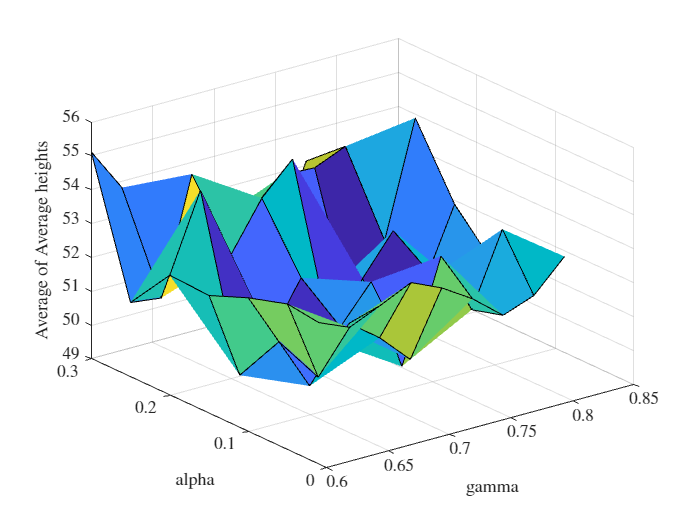


z_avg2 = zeros(7,9);

for i = 1:7
    z_avg2(i,:) = AvgAvgHeight2((i-1)*9+1:i*9);
end

surf(x2,y2,z_avg2)
ylabel("alpha")
xlabel("gamma")
zlabel("Average of Average heights")

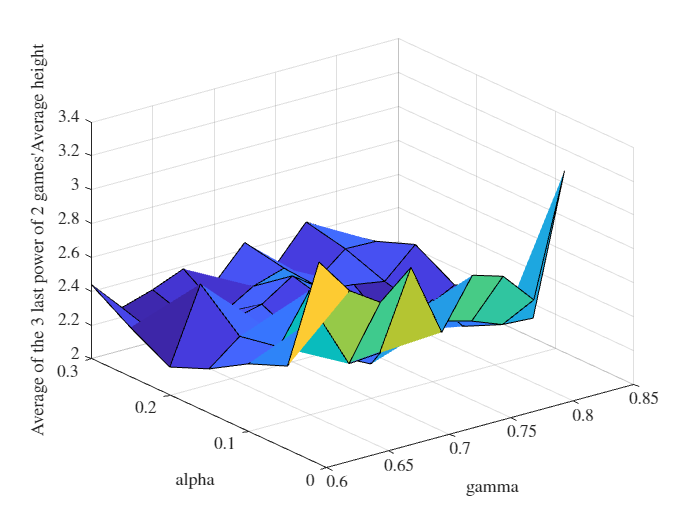



z_avg32 = zeros(7,9);

for i = 1:7
    z_avg32(i,:) = Avg3AvgHeight2((i-1)*9+1:i*9);
end
surf(x2,y2,z_avg32)
ylabel("alpha")
xlabel("gamma")
zlabel("Average of the 3 last power of 2 games'Average height")

=> best pair is gamma = 0.75 and alpha = 0.15

## 3 Play with reward function

The following metrics are used to calculate the reward function:

- loss (*Number of rows added to height when they're 'pushed down')*

- completed rows (number_of_completed_rows+above_row_completion)

- hole density

- bumpiness

reward = k_loss*loss + k_comp*(number_of_completed_rows+above_row_completion)

Everytime we can play with the coefficients associated to a metric

### 1 Play with loss & completed rows

The final metric will be the final/lowest height achieved after 2^11 games (not 2^13 for computation reasons)

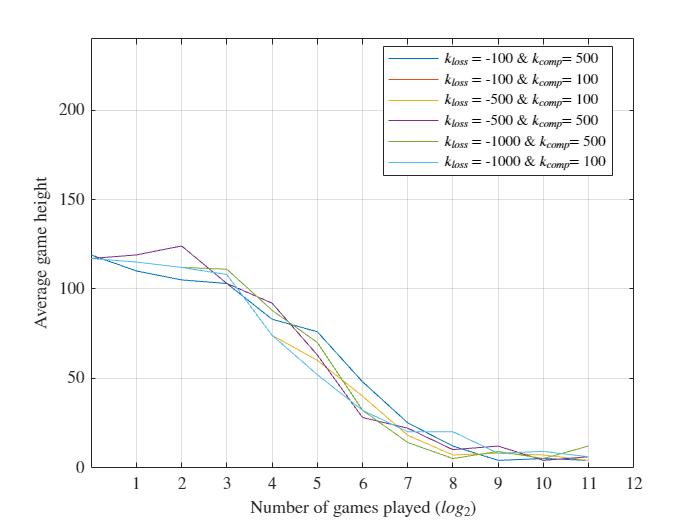

data1 = [1 240 0 767 119
2 221 0 1459 110
4 215 0 2786 105
8 230 0 5204 103
16 165 0 9577 83
32 151 0 16860 76
64 101 0 28223 48
128 35 0 44714 25
256 21 0 66138 12
512 5 0 91211 4
1024 4 0 114578 5
2048 2 0 135171 4]; % k_loss = -100 & k_comp = 500

data2 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -100 & k_comp = 100

data3 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 120 0 17081 60
64 83 0 28579 40
128 51 0 45085 18
256 10 0 66538 7
512 13 0 91651 8
1024 10 0 114908 7
2048 8 0 135470 4
]; % k_loss = -500 & k_comp = 100

data4 = [1 234 0 749 117
2 234 0 1456 119
4 256 0 2784 124
8 195 0 5214 103
16 187 0 9597 92
32 138 0 16945 63
64 46 0 28378 28
128 44 0 45087 22
256 14 0 66362 10
512 22 0 91248 12
1024 2 0 114415 4
2048 5 0 135733 6]; % k_loss = -500 & k_comp = 500

data5 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 220 0 5322 111
16 169 0 9759 88
32 147 0 17163 70
64 68 0 28687 32
128 27 0 45292 14
256 11 0 66763 5
512 9 0 91922 9
1024 5 0 115040 5
2048 14 0 135846 12]; % k_loss = -1000 & k_comp = 500

data6 = [1 234 0 771 117
2 233 0 1492 115
4 226 0 2818 112
8 209 0 5303 108
16 155 0 9735 74
32 102 0 17025 52
64 76 0 28613 32
128 23 0 45113 20
256 22 0 66161 20
512 11 0 91229 8
1024 23 0 114497 9
2048 4 0 135744 6]; % k_loss = -1000 & k_comp = 100

data = zeros(12,5,2);
data(:,:,1) = data1;
data(:,:,2) = data2;
data(:,:,3) = data3;
data(:,:,4) = data4;
data(:,:,5) = data5;
data(:,:,6) = data6;

subplot
for i = 1:size(data,3)
    plot(log2(data(:,1,i)), data(:,5,i))
    hold on
end
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("Average game height")
xticks(1:12)
axis([0 12 0 max(data1(:,2))])
legend("$k_{loss}$ = -100 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -100 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 100", ...
    "$k_{loss}$ = -500 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 500", ...
    "$k_{loss}$ = -1000 \& $k_{comp}$= 100")

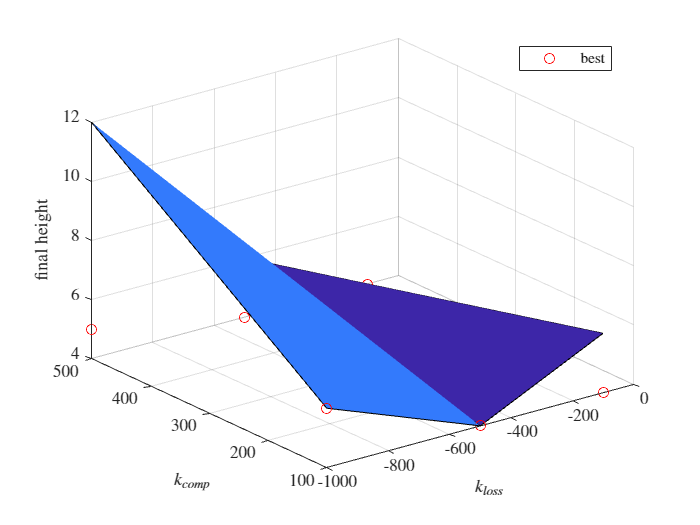


x3 = [-1000 -500 -100];
y3 = [100 500];
z3 = [data6(end,5) data3(end,5) data2(end,5); data5(end,5) data4(end,5) data1(end,5)];
%z2 = [min(data3(:,2)) min(data2(:,2)); min(data4(:,2)) min(data1(:,2))];
x2 = [-100 -100 -500 -500 -1000 -1000];
y2 = [500 100 100 500 500 100];
z2 = [min(data1(:,5)) min(data2(:,5)) min(data3(:,5)) min(data4(:,5)), min(data5(:,5)), min(data6(:,5))];
surf(x3,y3,z3)
hold on
plot3(x2,y2,z2, 'ro')
hold off
xlabel("$k_{loss}$")
ylabel("$k_{comp}$")
zlabel("final height")
legend("", "best")

v2

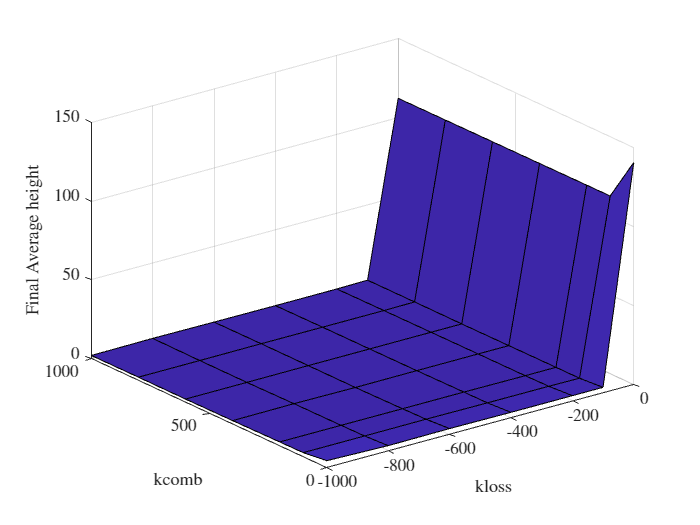

log_data = zeros(12,5,49);
log_data(:,:,1) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,2) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,3) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,4) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,5) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,6) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,7) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=0_kdens_=0_kbump_=0.txt');
log_data(:,:,8) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,9) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,10) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,11) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,12) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,13) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,14) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=100_kdens_=0_kbump_=0.txt');
log_data(:,:,15) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,16) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,17) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,18) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,19) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,20) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,21) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=200_kdens_=0_kbump_=0.txt');
log_data(:,:,22) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,23) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,24) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,25) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,26) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,27) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,28) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=400_kdens_=0_kbump_=0.txt');
log_data(:,:,29) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,30) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,31) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,32) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,33) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,34) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,35) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,36) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,37) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,38) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,39) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,40) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,41) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,42) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=800_kdens_=0_kbump_=0.txt');
log_data(:,:,43) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-1000_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,44) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-800_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,45) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-600_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,46) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-400_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,47) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-200_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,48) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=1000_kdens_=0_kbump_=0.txt');
log_data(:,:,49) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=0_kcomb_=1000_kdens_=0_kbump_=0.txt');

finalAvgHeight = log_data(end,end,:);
AvgAvgHeight = mean(log_data(:,end,:),1);
Avg3AvgHeight = mean(log_data(end-2:end,end,:),1); %avg over 3 last power of 2

% int klosses[n_kloss] = {-1000, -800, -600, -400, -200, -100, 0};
% int kcombs[n_kcomb] = {0, 100, 200, 400, 600, 800, 1000};

x = [-1000, -800, -600, -400, -200, -100, 0];
y = [0, 100, 200, 400, 600, 800, 1000];

z_final = zeros(7,7);

for i = 1:7
    z_final(i,:) = finalAvgHeight((i-1)*7+1:i*7);
end

surf(x,y,z_final)
ylabel("kcomb")
xlabel("kloss")
zlabel("Final Average height")

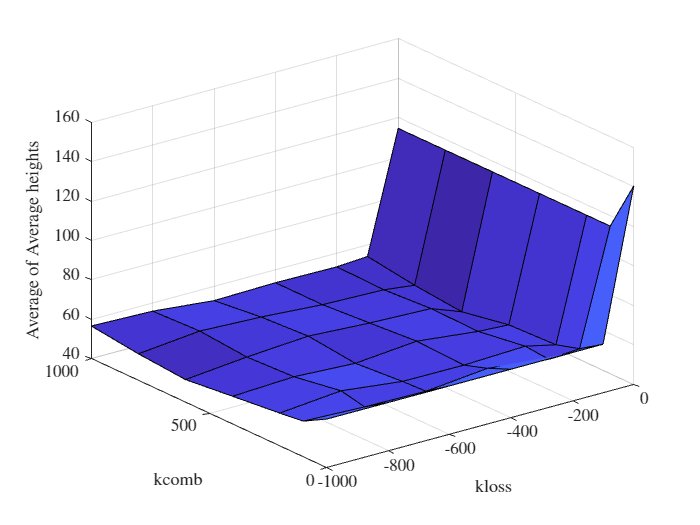


z_avg = zeros(7,7);

for i = 1:7
    z_avg(i,:) = AvgAvgHeight((i-1)*7+1:i*7);
end

surf(x,y,z_avg)
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of Average heights")

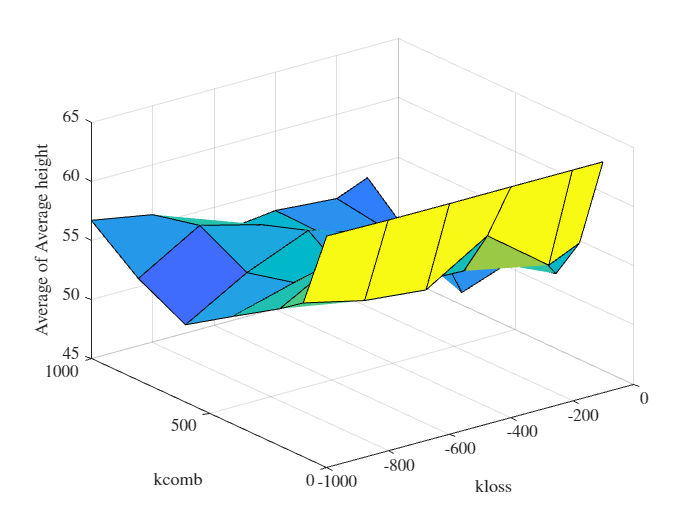

%remove kloss = 0
surf(x(1:end-1),y,z_avg(:,1:end-1))
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of Average height")

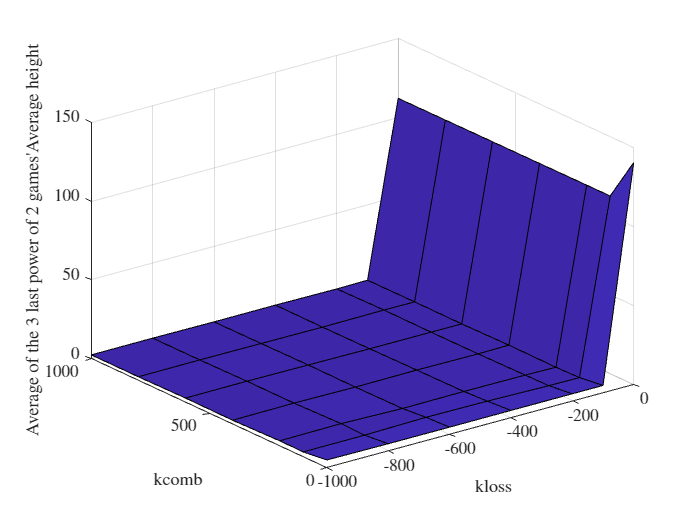

z_avg3 = zeros(7,7);

for i = 1:7
    z_avg3(i,:) = Avg3AvgHeight((i-1)*7+1:i*7);
end
surf(x,y,z_avg3)
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of the 3 last power of 2 games'Average height")

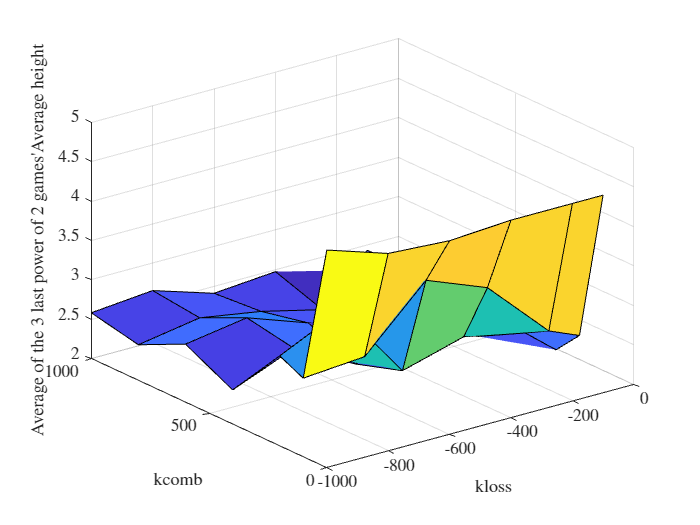

%remove kloss = 0
surf(x(1:end-1),y,z_avg3(:,1:end-1))
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of the 3 last power of 2 games'Average height")


%bestAvgHeight = min(AvgAvgHeight)

=> best pair is kloss = -100 and kcomb = 600

### 2 Play with hole density & bumpiness

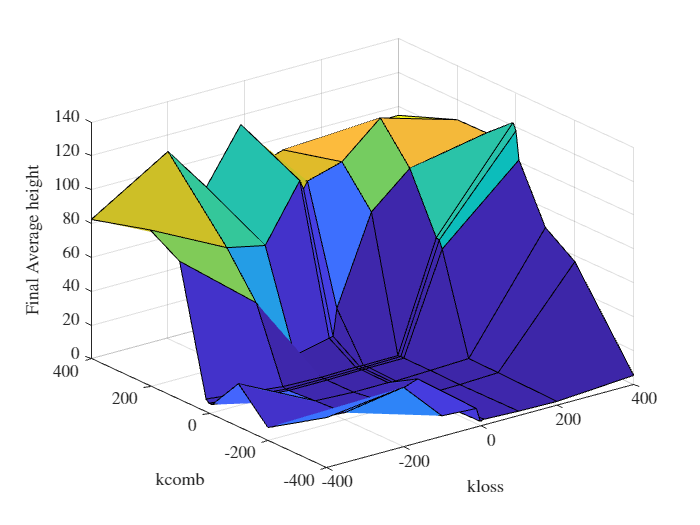

log_data = zeros(12,5,81);  %log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=-400
log_data(:,:,1) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=-400.txt');
log_data(:,:,2) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=-400.txt');
log_data(:,:,3) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=-400.txt');
log_data(:,:,4) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=-400.txt');
log_data(:,:,5) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=-400.txt');
log_data(:,:,6) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=-400.txt');
log_data(:,:,7) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=-400.txt');
log_data(:,:,8) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=-400.txt');
log_data(:,:,9) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=-400.txt');
log_data(:,:,10) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=-200.txt');
log_data(:,:,11) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=-200.txt');
log_data(:,:,12) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=-200.txt');
log_data(:,:,13) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=-200.txt');
log_data(:,:,14) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=-200.txt');
log_data(:,:,15) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=-200.txt');
log_data(:,:,16) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=-200.txt');
log_data(:,:,17) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=-200.txt');
log_data(:,:,18) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=-200.txt');
log_data(:,:,19) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=-100.txt');
log_data(:,:,20) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=-100.txt');
log_data(:,:,21) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=-100.txt');
log_data(:,:,22) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=-100.txt');
log_data(:,:,23) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=-100.txt');
log_data(:,:,24) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=-100.txt');
log_data(:,:,25) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=-100.txt');
log_data(:,:,26) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=-100.txt');
log_data(:,:,27) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=-100.txt');
log_data(:,:,28) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=-10.txt');
log_data(:,:,29) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=-10.txt');
log_data(:,:,30) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=-10.txt');
log_data(:,:,31) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=-10.txt');
log_data(:,:,32) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=-10.txt');
log_data(:,:,33) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=-10.txt');
log_data(:,:,34) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=-10.txt');
log_data(:,:,35) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=-10.txt');
log_data(:,:,36) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=-10.txt');
log_data(:,:,37) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=0.txt');
log_data(:,:,38) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=0.txt');
log_data(:,:,39) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=0.txt');
log_data(:,:,40) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=0.txt');
log_data(:,:,41) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=0.txt');
log_data(:,:,42) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=0.txt');
log_data(:,:,43) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=0.txt');
log_data(:,:,44) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=0.txt');
log_data(:,:,45) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=0.txt');
log_data(:,:,46) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=10.txt');
log_data(:,:,47) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=10.txt');
log_data(:,:,48) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=10.txt');
log_data(:,:,49) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=10.txt');
log_data(:,:,50) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=10.txt');
log_data(:,:,51) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=10.txt');
log_data(:,:,52) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=10.txt');
log_data(:,:,53) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=10.txt');
log_data(:,:,54) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=10.txt');
log_data(:,:,55) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=100.txt');
log_data(:,:,56) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=100.txt');
log_data(:,:,57) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=100.txt');
log_data(:,:,58) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=100.txt');
log_data(:,:,59) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=100.txt');
log_data(:,:,60) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=100.txt');
log_data(:,:,61) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=100.txt');
log_data(:,:,62) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=100.txt');
log_data(:,:,63) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=100.txt');
log_data(:,:,64) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=200.txt');
log_data(:,:,65) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=200.txt');
log_data(:,:,66) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=200.txt');
log_data(:,:,67) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=200.txt');
log_data(:,:,68) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=200.txt');
log_data(:,:,69) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=200.txt');
log_data(:,:,70) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=200.txt');
log_data(:,:,71) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=200.txt');
log_data(:,:,72) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=200.txt');
log_data(:,:,73) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-400_kbump_=400.txt');
log_data(:,:,74) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-200_kbump_=400.txt');
log_data(:,:,75) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-100_kbump_=400.txt');
log_data(:,:,76) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=-10_kbump_=400.txt');
log_data(:,:,77) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=0_kbump_=400.txt');
log_data(:,:,78) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=10_kbump_=400.txt');
log_data(:,:,79) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=100_kbump_=400.txt');
log_data(:,:,80) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=200_kbump_=400.txt');
log_data(:,:,81) = importdata('log_gamma_=0.750000_alpha_=0.150000_kloss_=-100_kcomb_=600_kdens_=400_kbump_=400.txt');

finalAvgHeight = log_data(end,end,:);
AvgAvgHeight = mean(log_data(:,end,:),1);
Avg3AvgHeight = mean(log_data(end-2:end,end,:),1); %avg over 3 last power of 2

% int kdenses[n_kdens] = {-400, -200, -100, -10, 0, 10, 100, 200, 400};
% int kbumps[n_kbump] = {-400, -200, -100, -10, 0, 10, 100, 200, 400};

x = [-400, -200, -100, -10, 0, 10, 100, 200, 400];
y = [-400, -200, -100, -10, 0, 10, 100, 200, 400];

z_final = zeros(9,9);

for i = 1:9
    z_final(i,:) = finalAvgHeight((i-1)*9+1:i*9);
end

surf(x,y,z_final)
ylabel("kcomb")
xlabel("kloss")
zlabel("Final Average height")

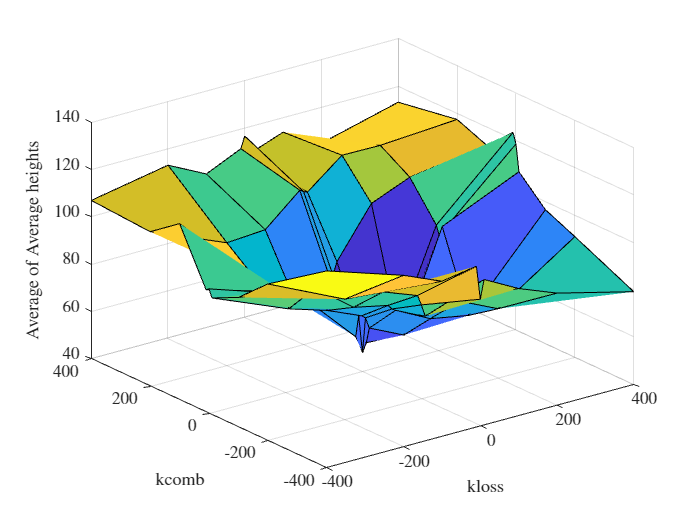


z_avg = zeros(9,9);

for i = 1:9
    z_avg(i,:) = AvgAvgHeight((i-1)*9+1:i*9);
end

surf(x,y,z_avg)
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of Average heights")

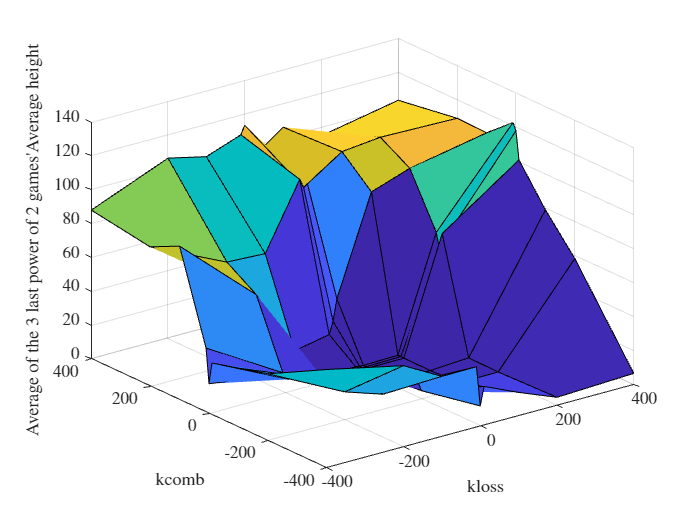


z_avg3 = zeros(9,9);

for i = 1:9
    z_avg3(i,:) = Avg3AvgHeight((i-1)*9+1:i*9);
end
surf(x,y,z_avg3)
ylabel("kcomb")
xlabel("kloss")
zlabel("Average of the 3 last power of 2 games'Average height")

=> bumpiness and hole density are not worth it!

## 4 Performance metric

Final height vs evolution during the game

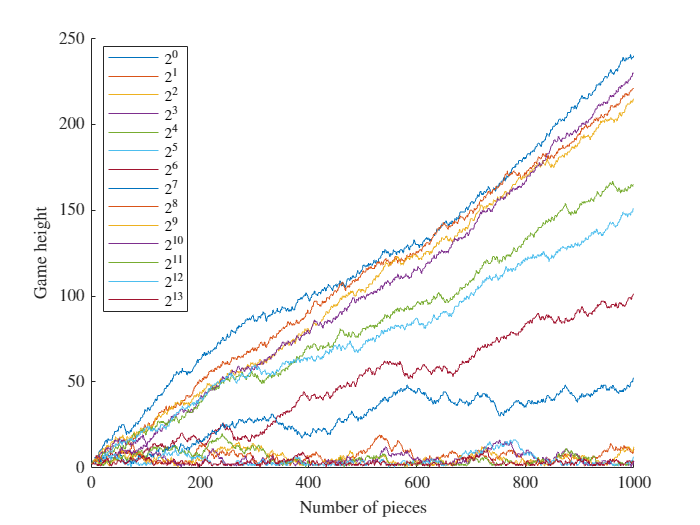

% load heights.txt
log_data = importdata('heights.txt');

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) %if a power of two
        max_i = i;
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

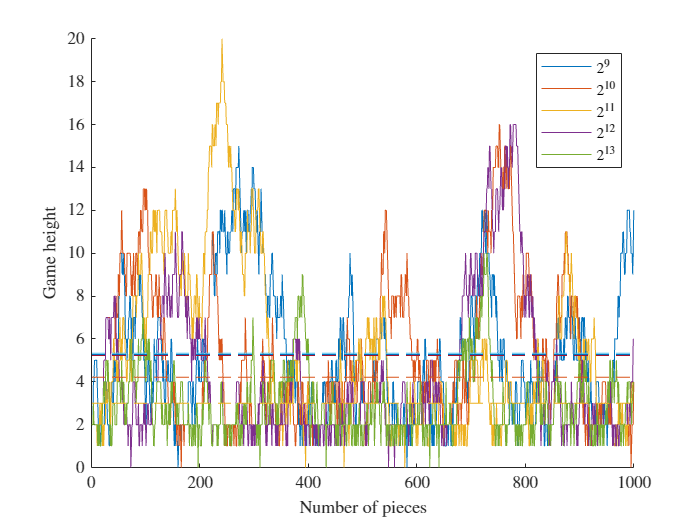


% mean and variance

mean_data = zeros(max_i,1);
var_data= zeros(max_i,1);

for i = 1:size(log_data, 1)
    mean_data(i) = mean(log_data(i,:));
    var_data(i) = var(log_data(i,:));
end

%last 5 powers of 2

figure
hold on
legend_str = cell(1, ceil(log2(size(log_data, 1))));
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
        plot(1:length(log_data(i,:)),log_data(i,:))
        legend_str{log2(i)+1} = ['$2^{' num2str(log2(i)) '}$'];
    end
end
hold off

legend(legend_str(~cellfun('isempty',legend_str)))
xlabel('Number of pieces')
ylabel('Game height')

hold on
for i = 1:size(log_data, 1)
    if ~bitand(i, i-1) && i>2^(13-5) %if a power of two
        plot([1 length(log_data(i,:))], [mean_data(i) mean_data(i)], '--')
    end
end
hold off

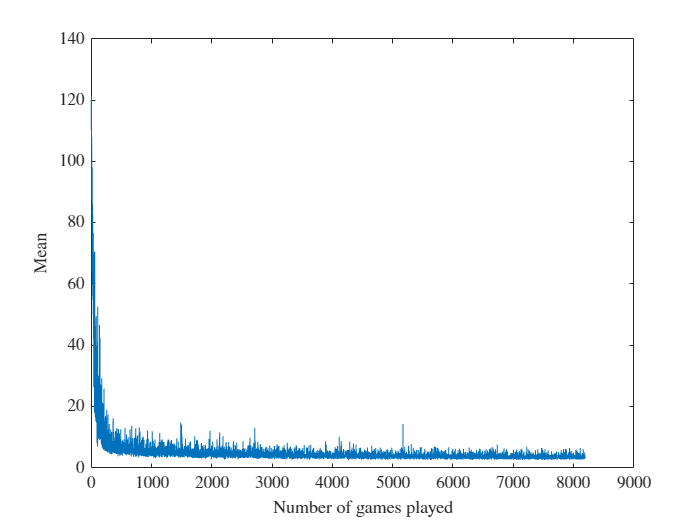


plot((1:size(log_data, 1)), mean_data)
ylabel("Mean")
xlabel("Number of games played")

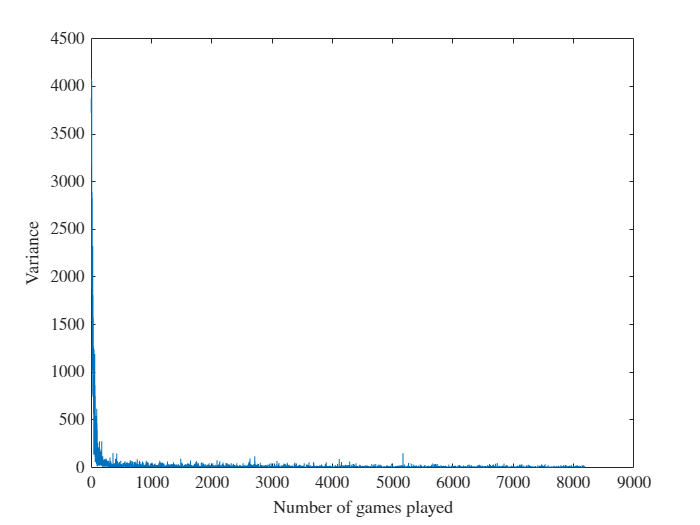


plot((1:size(log_data, 1)), var_data)
ylabel("Variance")
xlabel("Number of games played")

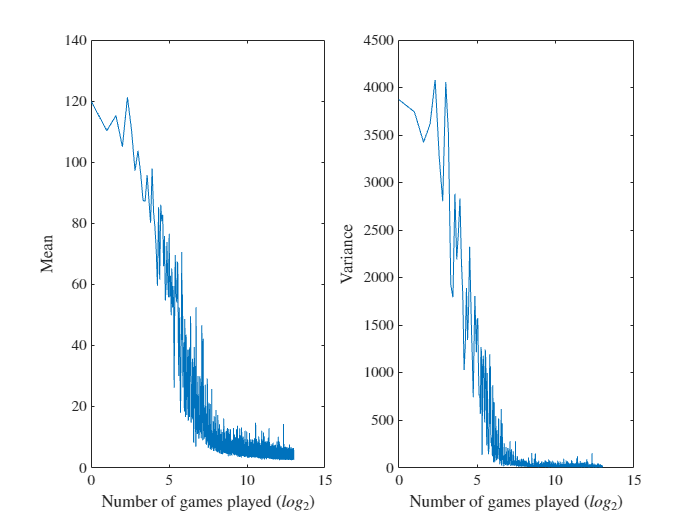


subplot(1,2,1)
plot(log2(1:size(log_data, 1)), mean_data)
ylabel("Mean")
xlabel("Number of games played ($log_2$)")
subplot(1,2,2)
plot(log2(1:size(log_data, 1)), var_data)
xlabel("Number of games played ($log_2$)")
ylabel("Variance")

# Discussion over the exploration method

For the following discussion we will always use the following cost function and parameters:

reward = loss*-100 + (number_of_completed_rows+above_row_completion)*500;

**float** gamma = 0.80f;*        // Discount factor*

**float** alpha = 0.02f;*        // Learning rate*

## 1 Random exploration method

exploration function = RandomExplorationMethod

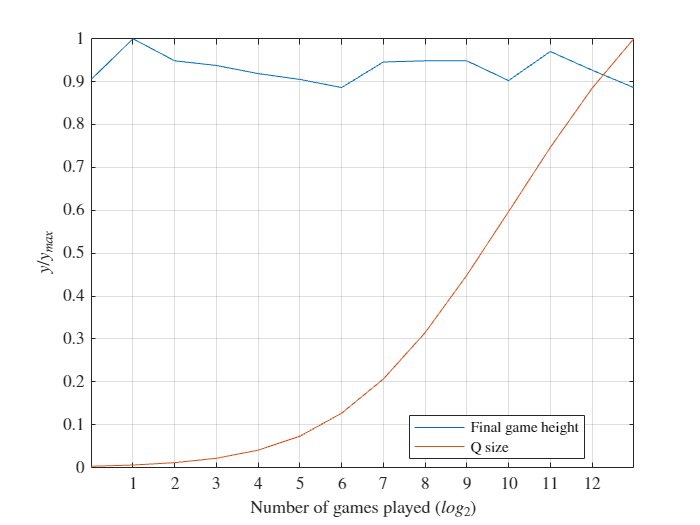

data1 = [1, 334, 0, 803
2, 369, 0, 1595
4, 350, 0, 3137
8, 346, 0, 5979
16, 339, 0, 11252
32, 334, 0, 20314
64, 327, 0, 35218
128, 349, 0, 57371
256, 350, 0, 87427
512, 350, 0, 124718
1024, 333, 0, 165909
2048, 358, 0, 207577
4096, 342, 0, 245911
8192, 327, 0, 278052];

figure
plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
%plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
%legend("Final game height", "Epsilon", "Q size")
legend("Final game height", "Q size")
xticks(1:12)
axis([0 13 0 1])

## 2 Epsilon greedy exploration method

### 1 Basic

epsilon = 0.1 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))

Index in position 2 exceeds array bounds.

hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 2 Play with epsilon

epsilon = 0:0.1:0.9 and no decay

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")


### 3 Play with decay

epsilon = 0.1 and decay 

`if`` (``EPSILON` `>` `0.001``) ``EPSILON` `*=` `0.99``; ``else` `EPSILON` `=` `0`

data1 = [1 250 0.1 800 122
2 250 0.099 1499 125
4 250 0.0970299 2855 128
8 241 0.0932065 5384 119
16 184 0.0860058 9841 92
32 125 0.0732303 17474 61
64 128 0.0530906 29537 70
128 33 0.0279042 46983 19
256 36 0.00770858 69435 13
512 7 0 94554 5
1024 11 0 117495 4
2048 2 0 137197 4
4096 4 0 154878 3
8192 9 0 169316 4];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
plot(log2(data1(:,1)), data1(:,5)./max(data1(:,5)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size", "Average game height")

## 3 Simple exploration method

### 1 Basic

 **int** N_MAX = 10;

 **double** R_PLUS = 20.0;

data1 = [];

plot(log2(data1(:,1)), data1(:,2)./max(data1(:,2)))
hold on
plot(log2(data1(:,1)), data1(:,3)./max(data1(:,3)))
plot(log2(data1(:,1)), data1(:,4)./max(data1(:,4)))
hold off
grid on
xlabel("Number of games played ($log_2$)")
ylabel("$y/y_{max}$")
legend("Final game height", "Epsilon", "Q size")

### 2 Play with Nmax & Rplus

(...)

# Computing time, convergence rate, stability, ...

(...)